Here is a $4\times 4$ Chebyshev differentiation matrix.

[t,Dx] = diffcheb(3,[-1 1]);
format rat, Dx

Dx =      -19/6            4             -4/3            1/2     
      -1              1/3            1             -1/3     
       1/3           -1             -1/3            1       
      -1/2            4/3           -4             19/6     


We again test the convergence rate. 

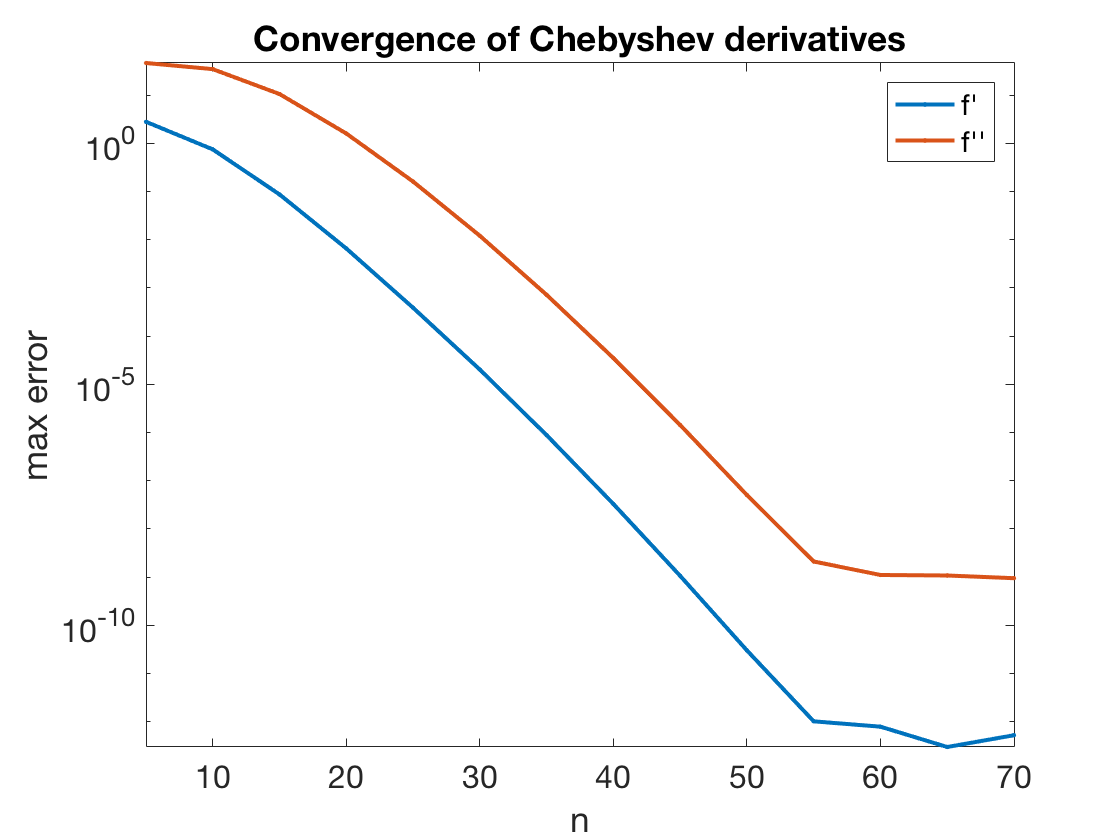

f = @(x) x + exp(sin(4*x));
dfdx = @(x) 1 + 4*exp(sin(4*x)).*cos(4*x);
d2fdx2 = @(x) 4*exp(sin(4*x)).*(4*cos(4*x).^2-4*sin(4*x));

n = (5:5:70)';
err1 = 0*n;
err2 = 0*n;

for k = 1:length(n)
    [t,Dx,Dxx] = diffcheb(n(k),[-1 1]);
    y = f(t);
    err1(k) = norm( dfdx(t) - Dx*y, inf );
    err2(k) = norm( d2fdx2(t) - Dxx*y, inf );
end
semilogy(n,[err1,err2],'.-'), hold on
axis tight, legend('f''','f''''')   % ignore this line
xlabel('n'), ylabel('max error')   % ignore this line
title('Convergence of Chebyshev derivatives')   % ignore this line

Notice that the graph has a log-linear scale, not log-log. Hence the convergence is exponential, as we expect for a spectral method on a smooth function. 